% 参数设置
Lx = 1; Ly = 1;
M = 0;
D = 0;
alpha = 0;
N = [64,64];
K = [30,30];
w = 0.01;
R = 0.0769;
lambda0 = 0.015;

ans = 127.3128


Diagnostic information:
Fitness function: @(x)(1-w)*(psll1(x)+psll2(x))+w*(energy2(x)+energy1(x))
Nonlinear constraint function: @(x)constraints(x,N,R,Lx,Ly,R1)
256 Variable(s)
8128 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
PopulationSize:    200
Generations:       100
TolFun:            0 
TolCon:            1e-06
InitialPopulation: 1-by-256
Display:           'diagnose'
PlotFcns:          @gaplotbestf
OutputFcns:        @GAoutputfcn
UseParallel:       1 
End of diagnostic information.

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          10100       121.682    8.201e-07      0
    2          25510        110.79    8.201e-07      0
    3          44720       96.2007            0      0
    4          63930       87.5768            0      0
    

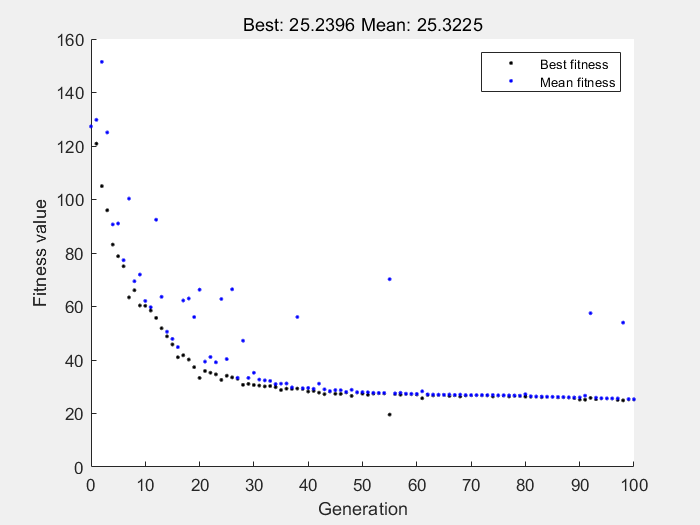

% start_points = hyperuniform_points;
start_points = [Lx, Ly] .* rand(sum(N),2);
hyperuniform_points = optimize_points(start_points, N, Lx, Ly, K, R, w, 0);

% start_points = [Lx, Ly] .* rand(N,2);
% start_points = hyperuniform_points;
% hyperuniform_points = generate_hyperuniform_points(start_points, N, Lx, Ly, K, R, D, alpha, w);

% hyperuniform_points = cut_circle(hyperuniform_points, N, Lx, Ly);
% hyperuniform_points = hyperuniform_points(all(~isnan(hyperuniform_points), 2), :);

% hyperuniform_points = reshape(bestXs, N, 2);
% hyperuniform_points = [all_points{1};all_points{2}];
min_distance = Inf;
for i = 1:size(hyperuniform_points, 1)-1
    for j = i+1:size(hyperuniform_points, 1)
        % 计算两点之间的欧几里得距离
        distance = norm(hyperuniform_points(i, :) - hyperuniform_points(j, :));
        
        % 更新最小距离
        if distance < min_distance
            min_distance = distance;
        end
    end
end
min_distance

min_distance = 0.0769

% 
% all_points{1} = hyperuniform_points(1:N(1), :);
% all_points{2} = hyperuniform_points(N(1)+1:end, :);
calPSLL3D(hyperuniform_points,0,0,20e9, 6.5*lambda0, 6.5*lambda0, sqrt(2*277/4/pi)*ones(370, 64), angles_uv)

ans = -10.7512

calPSLL3D(all_points{1},-60,90,20e9, 6.5*lambda0, 6.5*lambda0)

ans = -10.2836

calPSLL3D(all_points{2},-60,0,30e9, 6.5*lambda0, 6.5*lambda0)

ans = -8.5818

calPSLL3D(all_points{2},-60,90,30e9, 6.5*lambda0, 6.5*lambda0)

ans = -7.7866

total_potential_energy(all_points{1}, N(1), Lx, Ly, K(1), D, alpha) 

ans = 4.1665e+04

total_potential_energy(all_points{2}, N(2), Lx, Ly, K(2), D, alpha) 

索引超过数组元素的数量。索引不能超过 1。

% 绘制点分布
figure ;
hold on;
% scatter(hyperuniform_points(:, 1), hyperuniform_points(:, 2), 100, '.');
scatter(6.5*all_points{1}(:, 1), 6.5 * all_points{1}(:, 2), 2000, 'blue','.');
scatter(6.5*all_points{2}(:, 1), 6.5 * all_points{2}(:, 2), 1000, 'red','.');
axis equal;  
xlim([0, 6.5 * Lx]);
ylim([0, 6.5 * Ly]);
title('Hyperuniform 点分布'); 
box on;
hold off;
% 绘制圆
% hold on;
% theta = 0:0.01:2*pi;
% x_circle = Lx/2 * cos(theta) + Lx/2;
% y_circle = Lx/2 * sin(theta) + Lx/2;
% plot(x_circle, y_circle, 'LineWidth', 1);
% hold off;

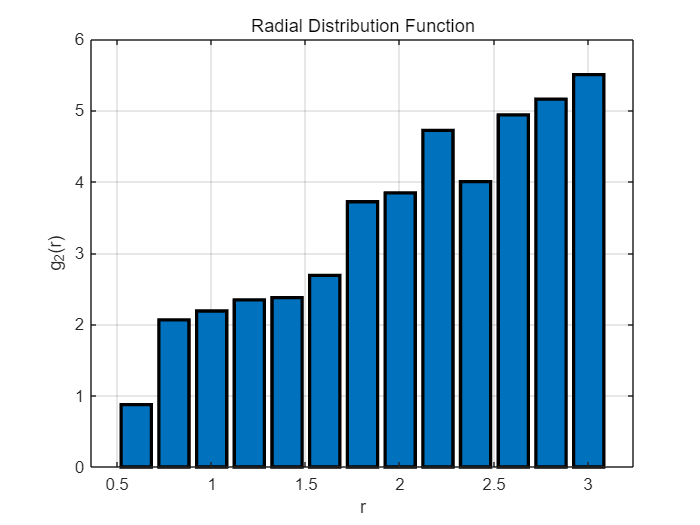

points =all_points{1};
plotg2(points, 0.0308, 0.0769, 1/2);

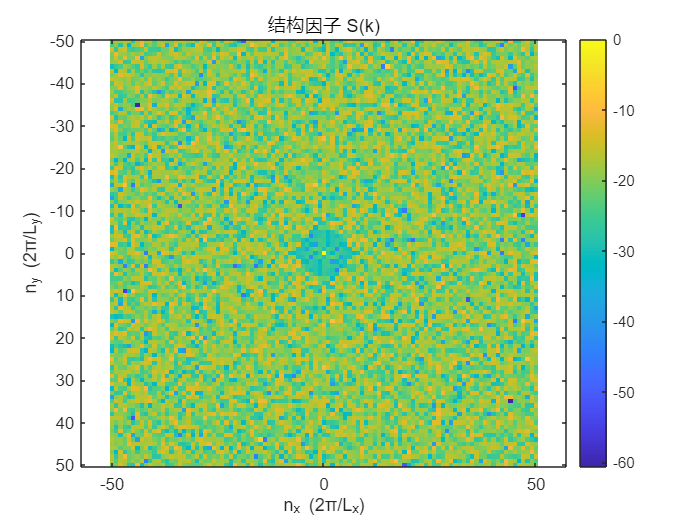


hypuniform_points = all_points{1};
N = 64;K = 30;

% 定义倒空间波矢范围
k_max = 50;         % 最大波矢值（单位：2π/L）
k_resolution = 101; % 分辨率
[kx, ky] = meshgrid(linspace(-k_max, k_max, k_resolution), ...
                    linspace(-k_max, k_max, k_resolution));

% 计算结构因子 S(k)
S = zeros(size(kx));
Mk = 0;
for i = 1:numel(kx)
    k = 2 * pi * [kx(i)/Lx, ky(i)/Ly];  % 波矢定义（实际物理单位）
    if kx(i) ^2 + ky(i) ^2 <= K
        Mk = Mk+1;
    end
    sum_exp = 0;
    for j = 1:N
        sum_exp = sum_exp + exp(1j * dot(k, hyperuniform_points(j, :)));
    end
    S(i) = abs(sum_exp)^2 / N;
end

Mk = (Mk-1)/2;
chi = Mk /2 /N;
norm_S = 10 * log10(S / max(S(:)));
% 绘制结构因子
figure (2);
imagesc(kx(1,:), ky(:,1), norm_S); % 对数刻度，避免 log(0)
axis equal;
xlabel('n_x (2π/L_x)');
ylabel('n_y (2π/L_y)');
title('结构因子 S(k)');
colorbar;

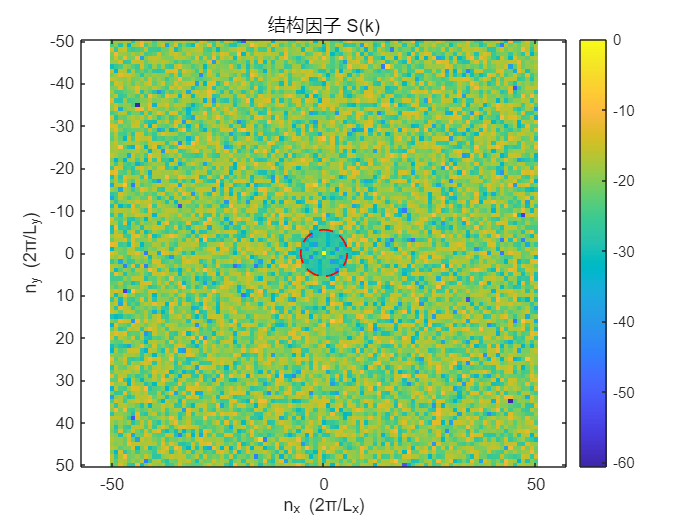

% 叠加截止区域圆（K）
hold on;
theta = 0:0.01:2*pi;
x_circle = sqrt(K) * cos(theta);
y_circle = sqrt(K) * sin(theta);
plot(x_circle, y_circle, 'r--', 'LineWidth', 1);
hold off;

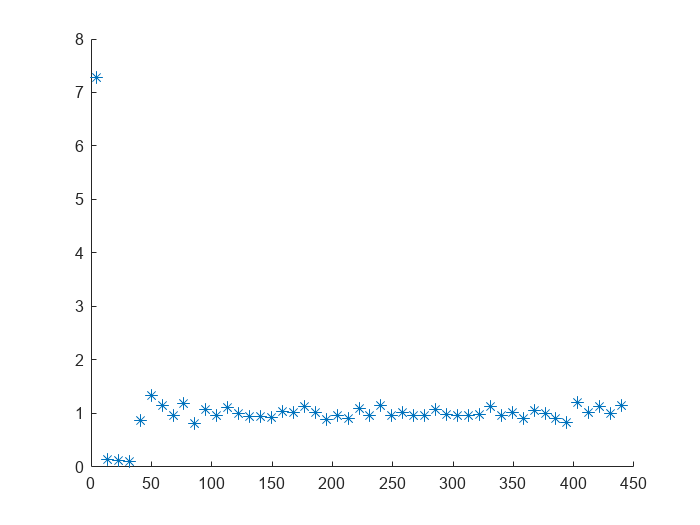

% 计算波矢模长 |k|
norm_k = 2 * pi / Lx * sqrt(kx.^2 + ky.^2);  % 注意！单位：2π/L
norm_k_flat = norm_k(:);        % 展平为一维数组
S_flat = S(:);                  % 展平为一维数组

% 定义模长平均的范围
bin_edges = linspace(0, max(norm_k_flat), 50);  % 100 个 bins
bin_centers = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;

% 将 S(k) 按 |k| 分组并计算平均值
S_mean = zeros(1, length(bin_centers));
for i = 1:length(bin_edges)-1
    mask = (norm_k_flat >= bin_edges(i)) & (norm_k_flat < bin_edges(i+1));
    S_mean(i) = mean(S_flat(mask));
end

% 绘制 S(k) 随 |k| 的变化曲线
figure;
scatter(bin_centers, S_mean, 50, '*'); 

xline(K_, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Cutoff K');

函数或变量 'K_' 无法识别。

ylim([0, 2]);

function points = optimize_points(start_points, N, Lx, Ly, K, R, w, R1)

    points = [reshape(start_points(1:N(1), :), 1, []), reshape(start_points(N(1)+1:end, :), 1, [])];

    energy1 = @(x) total_potential_energy(x(1 : N(1)*2), N(1), Lx, Ly, K(1), 0, 0);
    energy2 = @(x) total_potential_energy(x(2*N(1)+1 : 2*N(1)+2*N(2)), N(2), Lx, Ly, K(2), 0, 0);

    psll1 = @(x) calPSLL3D(reshape(x(1 : N(1)*2), N(1), 2),-60,0,20e9,0.0975,0.0975)...
                +calPSLL3D(reshape(x(1 : N(1)*2), N(1), 2),-60,90,20e9,0.0975,0.0975);

    psll2 = @(x)calPSLL3D(reshape(x (2*N(1)+1 : end), N(2), 2) ,-60,0,30e9,0.0975,0.0975)...
              + calPSLL3D(reshape(x (2*N(1)+1 : end), N(2), 2) ,-60,90,30e9,0.0975,0.0975);
    objective =  @(x) (1-w) * (psll1(x) + psll2(x))...
                + w * (energy2(x) + energy1(x));

    objective(points)
    % 定义约束条件
    nonlcon = @(x) constraints(x, N, R, Lx, Ly, R1);

    % 示例：使用遗传算法
    options_ga = optimoptions('ga', ...
        'InitialPopulationMatrix',points,...
        'PopulationSize', 200, ...
        'MaxGenerations', 100 , ...
        'FunctionTolerance', 0,...
        'ConstraintTolerance',1e-6,...
        'OutputFcn',@GAoutputfcn,...
        'Display','diagnose', 'UseParallel', true, ...
        'PlotFcn','gaplotbestf');
    optimized_points = ga(objective, 2*sum(N), [], [], [], [], zeros(2*sum(N), 1), ones(2*sum(N), 1), nonlcon, options_ga);
    points = [reshape(optimized_points(1 : N(1)*2), N(1), 2); reshape(optimized_points(2*N(1)+1 : end), N(2), 2)];
end

% function max_Sk = max_Sk(points, N, Lx, Ly, K, K1)
%     points = reshape(points, N, 2);
%     max_Sk = 0;
%     
%     for nx = -50:50
%         for ny = -50:50
%             if nx ^2 + ny^2 <= K1 & nx ^2 + ny^2 ~= 0
%                 k = 2 * pi * [nx/Lx, ny/Ly]; 
%                 Ck = 0;
%                 for j = 1:N-1
%                     for l = j+1:N
%                         Ck = Ck + cos(dot(k, points(j, :) - points(l, :)));
%                     end
%                 end
%                 if 1+2*Ck/N > max_Sk
%                     max_Sk = 1+2*Ck/N;
%                     max_k = [nx,ny];
%                 end
%             end
%         end
%     end
% %     assignin('base', 'max_k', max_k);
% end

function hyperuniform_points = generate_hyperuniform_points(start_points, N, Lx, Ly, K, R, D, alpha, w)
    % 生成 Hyperuniform 点分布
    % 输入参数：
    %   N: 点的数量
    %   Lx, Ly: 计算区域的边长
    %   K: 倒空间截止波数
    %   R: 点的最小间距（硬球半径）
    % 输出：
    %   hyperuniform_points: N x 2 矩阵，表示点的坐标

    % 初始化随机点分布
    points = start_points;
    
    % 定义优化目标函数
    objective =  @(x) 1 * total_potential_energy(x, N, Lx, Ly, K, D, alpha) + ...
        0 * total_potential_energy_2(x, N, Lx, Ly, K, D, alpha);

    % 定义约束条件
    nonlcon = @(x) constraints(x, N, R, Lx, Ly, [], 0);

    % 示例：使用遗传算法
%     options_ga = optimoptions('ga', 'PopulationSize', 100, 'MaxGenerations', 100, 'Display','iter', 'UseParallel', true);
%     optimized_points = ga(objective, 2*N, [], [], [], [], zeros(2*N, 1), ones(2*N, 1), nonlcon, options_ga);

%     优化选项
    options = optimoptions('fmincon', 'Algorithm', 'interior-point', ...
                           'Display', 'iter', 'MaxIterations', 200, ...
                           'ConstraintTolerance',1e-10,...
                           'FunctionTolerance',1,...
                           'MaxFunctionEvaluations', 500 * N, ...
                           'PlotFcn','optimplotfval');

%     调用 fmincon 进行优化
    optimized_points = fmincon(objective, points, [], [], [], [], ...
                               zeros(N, 2), [Lx, Ly] .* ones(N, 2), ...
                               nonlcon, options);

    % 返回优化后的点分布
    hyperuniform_points = optimized_points;
end

function phi = total_potential_energy(points, N, Lx, Ly, K, D, alpha) 
    % 计算总势能
    phi = 0;
    M = 0;
    points = reshape(points, N, 2); % 将向量转换为 N x 2 矩阵
    
    % 遍历所有波矢 k
    for nx = -50:50
        for ny = -50:50
            if nx ^2 + ny^2 <= K && nx ^2 + ny^2 ~= 0 % k在K内，相当于辅助函数
                k = 2 * pi * [nx / Lx, ny / Ly]; % 波矢
                C0 = -N/2 + D * norm(k) ^ alpha;
                Ck = 0;
                for j = 1:N-1
                    for l = j+1:N
                        Ck = Ck + cos(dot(k, points(j, :) - points(l, :)));
                    end
                end
                phi = phi + (C0 - Ck) ^2;
            end
        end
    end
end

function [c, ceq] = constraints(points, N, R, Lx, Ly, other_points, R1)
    % 定义约束条件
    points = [reshape(points(1 : N(1)*2), N(1), 2); reshape(points(2*N(1)+1 : end), N(2), 2)];
    c = []; % 不等式约束
    ceq = []; % 等式约束
    N = sum(N);
    % 最小间距约束
    for j = 1:N-1
        for l = j+1:N
            dist = norm(points(j, :) - points(l, :));
            c = [c; R - dist]; % 确保 dist >= R
        end
    end
    
end

function points = cut_circle(points, N, Lx, Ly)
    for n = 1:N
        if norm(points(n, :) - [Lx/2, Ly/2]) >= Lx/2
            points(n, :) = [NaN, NaN];
        end
    end
end    

function stop = myOutputFcn(~, optimValues, state)
    persistent targetValue
    if isempty(targetValue)
        targetValue = 0; % 设定目标函数值的阈值
    end
    
    stop = false;
    
    switch state
        case 'iter'
            % 在每次迭代时检查目标函数值
            if optimValues.fval <= targetValue
                disp(['目标函数值已达到: ', num2str(optimValues.fval)]);
                stop = true; % 终止优化
            end
    end
end

function [state,options,optchanged] = GAoutputfcn(options,state,flag)
    persistent overall_best_fval;
    persistent overall_best_x;
    
    if isempty(overall_best_fval) || strcmp(flag, 'init')
        overall_best_fval = Inf;
        overall_best_x = [];
    end
    
    if ~isempty(state.Score)
        [current_min, idx] = min(state.Score);
        
        % Only update if better than what we've seen before
        if current_min < overall_best_fval
            overall_best_fval = current_min;
            overall_best_x = state.Population(idx,:);
            assignin('base','bestXs',overall_best_x);
            assignin('base',"bestFvals",overall_best_fval);
        end
        
        % Display accurate information
%         fprintf('Generation %d: Current best = %f, Overall best = %f\n', ...
%                 state.Generation, current_min, overall_best_fval);
    end
    
    % Continue optimization
    optchanged = false;
end

